# Solución al problema del viajante con algoritmos genéticos.

Bryan Gustavo Paredes Ballesteros

¿Qué ruta seguir para visitar las 24 capitales de las provincias del Ecuador optimizando el camino y reduciendo la distancia recorrida?

clear;
clc;

## Codigo Principal

Importar el archivo Excel con las coordenadas de las ciudades.

ciudades = readmatrix('CoordenadasCapitalesProvinciasEcuador.xlsx');

datos = ciudades(:,[2 5 6])

datos = 1.0e+03 *

    0.0010    1.4257    0.6160
    0.0020    1.4093    0.4506
    0.0030    1.4230    0.5796
    0.0040    1.5387    0.1851
    0.0050    1.4364    0.4580
    0.0060    1.4382    0.3805
    0.0070    1.3245    0.6535
    0.0080    1.3403    0.1933
    0.0090    0.2485    0.3804
    0.0100    1.3257    0.5413



p=50; % Tamaño de la poblacion
c=30; % Numero de pares de cromosomas para el cruce
m=25; % numero de cromosomas para la mutacion

tg=300; % numero de generaciones
Fc = 10; % asignar la primera ciudad
Lc = 3; % Asignar la ultima ciudad

[x y] = size(datos);
nc = x; % numero de ciudades
figure
title('Evolucion de la distancia minima encontrada');
xlabel('Generacion')
ylabel('Distancia total recorrida')
hold on
  
P=poblacion(p,nc);

Y =     20    22     3    23    14     2     8    13    24    21     5    19    18    10    16     4     9    17    12    15     7     1    11     6
    17    19    18     9    15     4    16     1     7     2     5    22    20    10    24     3    12    11    21    14     6    13     8    23
    18    19     7    16    15     4     3    12    24     9    14     5    21     6    13    20    23    22    10     1     2     8    17    11
    20     6    23     9     4     7    16    13    10    21    15    14    24     5    18    17     8    11     1     2    19    22    12     3
    14    11     1     9     5    21     8    15     4    18     7    19    20    22    12     2     6    24     3    23    16    17    10    13
     3    24     1    19    20    21     4    10     8    18    12    22     6     7     5     9    17    15    14     2    23    13    11    16
    10     2     7     4     6     9    14     1    23    24    15    16    12    21    11     5    20    13     8    18     3

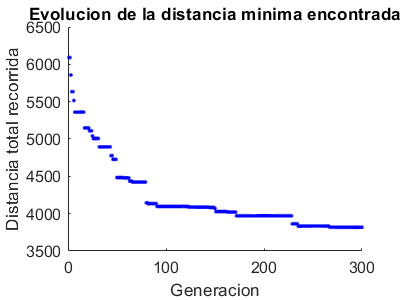

for i=1:tg   
            P(p+1:p+c,:)=cruce(P,c);
            P(p+c+1:p+c+m,:)=mutacion(P,m);
            P = reemplazo(P, Fc, Lc);
            E=evaluacion(P,datos);
            [P S]=seleccion(P,E,p);
            Mejor(i)=S(1,1);
            plot(Mejor(:),'b.'); 
            drawnow
            hold on
end

 
distanciaMinima=min(Mejor)

distanciaMinima = 3.8187e+03

solucionOptima=P(1,:)

solucionOptima =     10    13     5    17    22     4    11    15    24    12     1     7     8    21    19    16    18     6    23     2    14    20     9     3


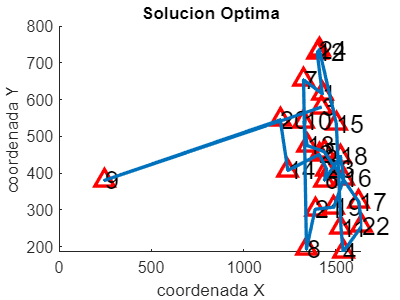

[x1 y1] = size(solucionOptima);
figure
title('Solucion Optima');
xlabel('coordenada X')
ylabel('coordenada Y')

hold on
coorx = datos(:,2);
coory = datos(:,3);
plot(coorx,coory,'^r','MarkerSize',10,'LineWidth',2)
for i=1:x
    text(datos(i,2)+0.2,datos(i,3)+0.2,num2str(i),'FontSize', 15);
end
datos2 = zeros(size(datos));
for i=1:y1
    datos2(i,:)= datos(solucionOptima(i),:);
end
line(datos2(:,2),datos2(:,3),'LineStyle', '-','LineWidth',2);

## Población del algoritmo genético

n = numero de las ciudades

nc = tamaño población

function Y=poblacion(n,nc)
B=zeros(n,nc);
for j=1:n
    A=1:1:nc;   
    [x y]=size(A);
    for i = 1:nc
        r = randi(y);
        B(j,i)=A(r);
        A(:,r) = [];
        [x y]=size(A);
    end
end
Y = B
end

## Cruce

X = poblacion

n = numero de cromosomas para cruzar

function XX=cruce(X,n)
[x1 y1] = size(X);
Y = zeros(n,y1);
 
for z = 1:n
    B = X(randi(x1),:); % seleccionar cromosoma de los padres
    r1 = 1 + randi(y1-1);
    C = B(1,1:r1);
    B(:,1:r1) = [];  % cortar
    [x3 y3] = size(B);
    B(1,y3+1:y1) = C;
    Y(z,:) = B;
end
XX = Y;
end

## Mutacion

X = poblacion

n = numero de cromosomas para mutar

function YY = mutacion(X,n)
[x1 y1]=size(X);
Y=zeros(n,y1);
 
for z=1:n
    A=X(randi(x1),:); % seleccion del cromosoma de los padres
    r1=1+randi(y1-1,1,2);
    while r1(1)==r1(2)
            r1=1+randi(y1-1,1,2);
    end
    B=A(1,r1(1));
    A(1,r1(1))=A(1,r1(2));
    A(1,r1(2))=B;
    Y(z,:)=A;
end
YY = Y;
end

## Evaluacion

P = poblacion

datos = ubicaciones de las capitales de las provincias

function ZZ = evaluacion(P,datos)
[x0 y0] = size(P);

for i = 1:x0
    B = P(i,:); % Seleccionar un cromosoma
    A = zeros(size(B));
    for j1 = 1:y0-1
        [x1 y1] = find(datos(:,1)==B(1,j1));
        [x2 y2] = find(datos(:,1)==B(1,j1+1));
        A(1,j1) = sqrt((datos(x1,2)-datos(x2,2))^2+(datos(x1,3)-datos(x2,3))^2);
    end
    [x1 y1] = find(datos(:,1)==B(1,1));
    [x2 y2] = find(datos(:,1)==B(1,y0));
    A(1,j1) = sqrt((datos(x1,2)-datos(x2,2))^2+(datos(x1,3)-datos(x2,3))^2);
    Y(1,i)=1/sum(A);
end
ZZ = Y;
end

## Seleccion

P1 = Poblacion

b = valor de fitness

p = tamaño de la poblacion

function [YY1 YY2]=seleccion(P1,B,p)
[r1 c1]=find(B==max(B));
Y1(1,:)=P1(max(c1),:); % Encontrar el mejor primero
Fn(1,1)=1/B(1,max(c1)); % mejor valor de fitness 
% Determinar el fitness total de la poblacion
C=sum(B);
% Probabilidad de Seleccion
D=B/C;
% Probabilidad acumulativa 
E= cumsum(D);

N=rand(1);
d1=1;
d2=1;
while d2 <= p-1
    if N <= E(d1)
       Y1(d2+1,:)=P1(d1,:); 
       Fn(1,d2+1)=1/B(1,d1);
       N=rand(1);
       d2 = d2 +1; 
       d1=1;
     else
        d1 = d1 + 1;
    end
end
YY1=Y1;
YY2=Fn;
end

## Reemplazar

function Y=reemplazo(X,Fc,Lc)
[x y]=size(X);
A=zeros(x,y);
for i=1:x
    B = X(i,:);
    [x1 y1] = find(B == Fc);
    B(:,y1)=[];
    [x2 y2] = find(B == Lc);
    B(:,y2)=[];
    A(i,1)=Fc;
    A(i,2:y-1)=B;
    A(i,y)=Lc;
end
Y=A;
end